clear all;
clc;

## 直角坐标机器人建立

L1=Link([pi,1500,0,pi/2]);
L1.jointtype='P'; % 滑动关节
L1.qlim=[100,5000]; % 关节1最大活动限度
L2=Link([-pi/2,1500,0,pi/2]);
L2.jointtype='P'; % 滑动关节
L2.qlim=[100,5000]; % 关节2最大活动限度
L3=Link([-pi/2,1500,0,pi/2]);
L3.jointtype='P'; % 滑动关节
L3.qlim=[100,5000]; % 关节3最大活动限度

## 刀头建模

刀头D-H参数

theta=[pi/2,3*pi/4,pi,pi/4,pi/2];
d=[0 0 -300/(sqrt(2)) 0 300 ];
a=[300 -300/sqrt(2) 0 -300 0];
alpha=[pi/2 pi/2 pi/2 pi/2 0];

刀头D-H参数和关节旋转限度

L4=Link([theta(1)    d(1)     a(1)     alpha(1)          ]);
L5=Link([theta(2)    d(2)     a(2)     alpha(2)          ]);
L5.qlim=[3*pi/4,3*pi/4];
L6=Link([theta(3)    d(3)     a(3)     alpha(3)          ]);
L7=Link([theta(4)    d(4)     a(4)     alpha(4)          ]);
L7.qlim=[-3*pi/4,-3*pi/4];
L8=Link([theta(5)    d(5)     a(5)     alpha(5)          ]);
L8.qlim=[pi/2,pi/2];

## 建立直角坐标水刀机器人

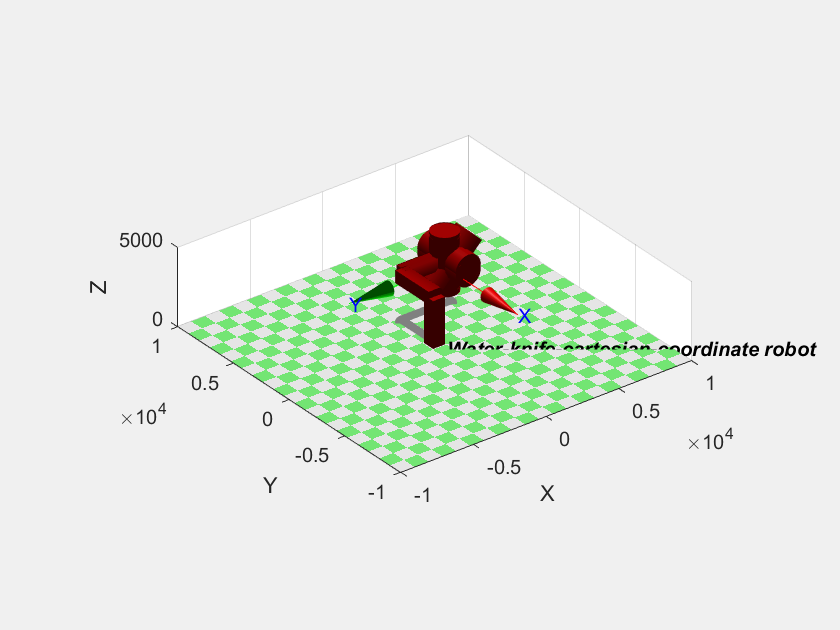

MyRobot=SerialLink([L1,L2,L3,L4,L5,L6,L7,L8] ,'name','Water-knife-cartesian-coordinate robot','base', transl(0,0,0)*trotz(0),'modified'); % 底座位置(0,0,0)
MyRobot.plot([3000,3000,3000,pi/2,3*pi/4,pi,pi/4,pi/2],'workspace',[-10000 10000 -10000 10000 0 5000]);

输入$delta$和$gamma$

% delta = input('Please input delta=');
% gamma = input('Please input gamma=');
delta=30;
gamma=30;

关节角度

theta=[CalBeta(delta,gamma),3*pi/4,CalTheta(delta,gamma),pi/4,pi/2];

圆心坐标和圆半径

circle=[3000,3000,2400];
R=2000;

移动步长

step=50;

## 运动轨迹可视化

 

ans = 
   -0.9881   -0.0983    0.1182      4984
   -0.1181   -0.0068   -0.9930      3251
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4937
   -0.1181   -0.0068   -0.9930      3497
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4860
   -0.1181   -0.0068   -0.9930      3736
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4753
   -0.1181   -0.0068   -0.9930      3964
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4618
   -0.1181   -0.0068   -0.9930      4176
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4458
   -0.1181   -0.0068   -0.9930      4369
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4275
   -0.1181   -0.0068   -0.9930      4541
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4072
   -0.1181   -0.0068   -0.9930      4689
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3852
   -0.1181   -0.0068   -0.9930      4810
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3618
   -0.1181   -0.0068   -0.9930      4902
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3375
   -0.1181   -0.0068   -0.9930      4965
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3126
   -0.1181   -0.0068   -0.9930      4996
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2874
   -0.1181   -0.0068   -0.9930      4996
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2625
   -0.1181   -0.0068   -0.9930      4965
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2382
   -0.1181   -0.0068   -0.9930      4902
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2148
   -0.1181   -0.0068   -0.9930      4810
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1928
   -0.1181   -0.0068   -0.9930      4689
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1725
   -0.1181   -0.0068   -0.9930      4541
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1542
   -0.1181   -0.0068   -0.9930      4369
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1382
   -0.1181   -0.0068   -0.9930      4176
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1247
   -0.1181   -0.0068   -0.9930      3964
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1140
   -0.1181   -0.0068   -0.9930      3736
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1063
   -0.1181   -0.0068   -0.9930      3497
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1016
   -0.1181   -0.0068   -0.9930      3251
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1000
   -0.1181   -0.0068   -0.9930      3000
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1016
   -0.1181   -0.0068   -0.9930      2749
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1063
   -0.1181   -0.0068   -0.9930      2503
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1140
   -0.1181   -0.0068   -0.9930      2264
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1247
   -0.1181   -0.0068   -0.9930      2036
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1382
   -0.1181   -0.0068   -0.9930      1824
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1542
   -0.1181   -0.0068   -0.9930      1631
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1725
   -0.1181   -0.0068   -0.9930      1459
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      1928
   -0.1181   -0.0068   -0.9930      1311
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2148
   -0.1181   -0.0068   -0.9930      1190
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2382
   -0.1181   -0.0068   -0.9930      1098
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2625
   -0.1181   -0.0068   -0.9930      1035
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      2874
   -0.1181   -0.0068   -0.9930      1004
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3126
   -0.1181   -0.0068   -0.9930      1004
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3375
   -0.1181   -0.0068   -0.9930      1035
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3618
   -0.1181   -0.0068   -0.9930      1098
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      3852
   -0.1181   -0.0068   -0.9930      1190
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4072
   -0.1181   -0.0068   -0.9930      1311
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4275
   -0.1181   -0.0068   -0.9930      1459
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4458
   -0.1181   -0.0068   -0.9930      1631
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4618
   -0.1181   -0.0068   -0.9930      1824
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4753
   -0.1181   -0.0068   -0.9930      2036
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4860
   -0.1181   -0.0068   -0.9930      2264
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4937
   -0.1181   -0.0068   -0.9930      2503
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      4984
   -0.1181   -0.0068   -0.9930      2749
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


 

ans = 
   -0.9881   -0.0983    0.1182      5000
   -0.1181   -0.0068   -0.9930      3000
    0.0984   -0.9951   -0.0049      1800
         0         0         0         1


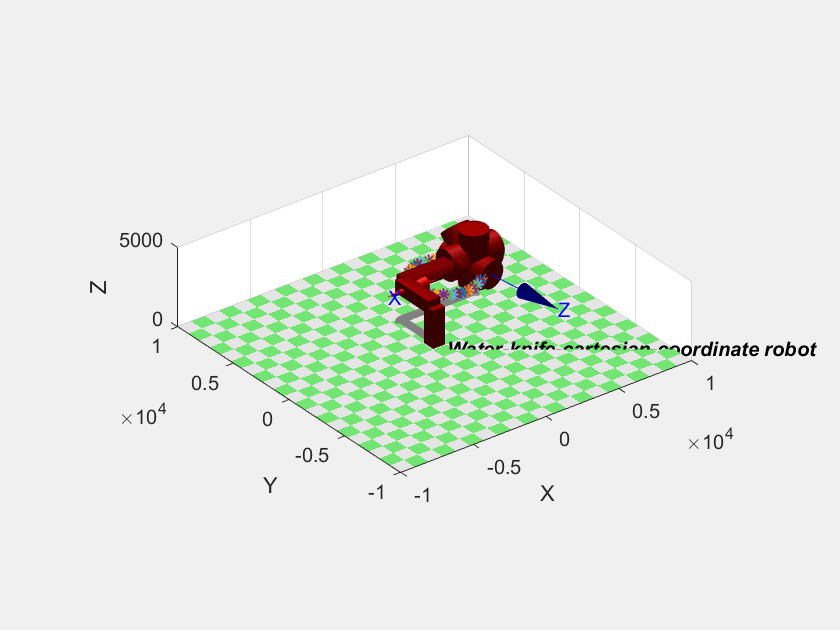

for i =1:step
    w=i*2*pi/step; % 圆上每次移动的圆心角
    JointMat=[circle(3),circle(2)+R*sin(w),circle(1)+R*cos(w),theta(1),theta(2),theta(3),theta(4),theta(5)]; % 关节运动参数
    fkine(MyRobot,JointMat)
    hold on
    grid on
    plot3(circle(1)+R*cos(w),circle(2)+R*sin(w),circle(3)-abs(d(3))*sqrt(2)-d(5),'*','LineWidth',1); % 绘制水刀切割的形状
    MyRobot.plot(JointMat); % 绘制机器人
end